# Assignment 5

# Use of Matlab to Investigate Compartmental Systems

**220735E **

**YASHODHARA.M.H.K.**

## Part 1

### Question 01

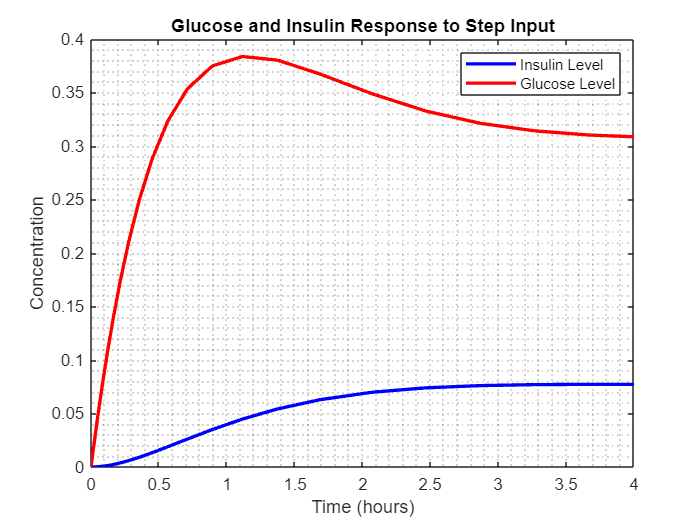

% Solve and plot glucose-insulin step response
clc;
clear;
close all;

[time, state] = ode23(@glucose_step_model, [0 4], [0 0]);
figure;
plot(time, state(:,1), 'b-', 'LineWidth', 2, 'DisplayName', 'Insulin Level');
hold on;
plot(time, state(:,2), 'r-', 'LineWidth', 2, 'DisplayName', 'Glucose Level');
xlabel('Time (hours)');
ylabel('Concentration');
title('Glucose and Insulin Response to Step Input');
legend('Location', 'northeast');
grid minor;

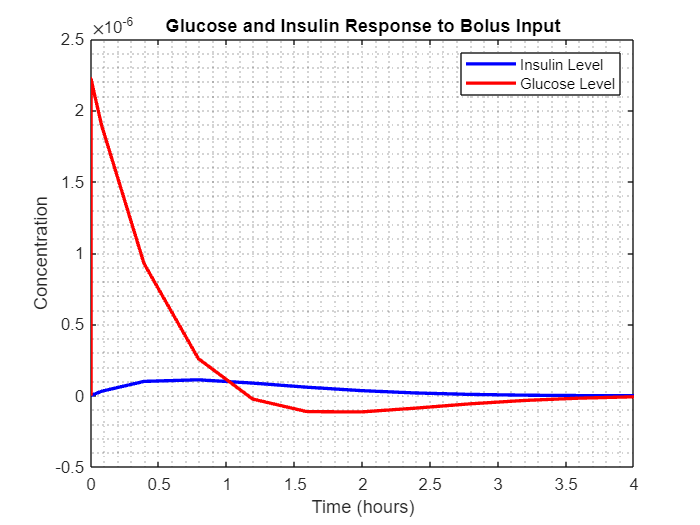

% Solve and plot glucose-insulin bolus input response
[time, state] = ode23(@glucose_bolus_model, [0 4], [0 0]);
figure;
plot(time, state(:,1), 'b-', 'LineWidth', 2, 'DisplayName', 'Insulin Level');
hold on;
plot(time, state(:,2), 'r-', 'LineWidth', 2, 'DisplayName', 'Glucose Level');
xlabel('Time (hours)');
ylabel('Concentration');
title('Glucose and Insulin Response to Bolus Input');
legend('Location', 'northeast');
grid minor;

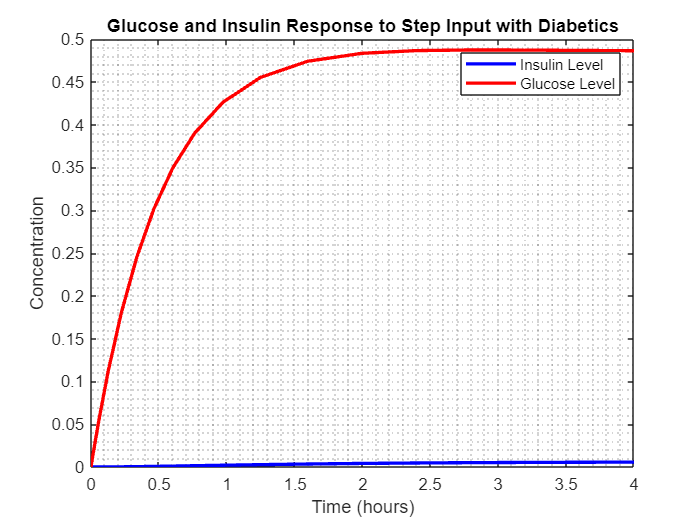

% Solve and plot glucose-insulin step input response for a subject with diabetics
[time, state] = ode23(@glucose_diabetic_model, [0 4], [0 0]);
figure;
plot(time, state(:,1), 'b-', 'LineWidth', 2, 'DisplayName', 'Insulin Level');
hold on;
plot(time, state(:,2), 'r-', 'LineWidth', 2, 'DisplayName', 'Glucose Level');
xlabel('Time (hours)');
ylabel('Concentration');
title('Glucose and Insulin Response to Step Input with Diabetics');
legend('Location', 'northeast');
grid minor;

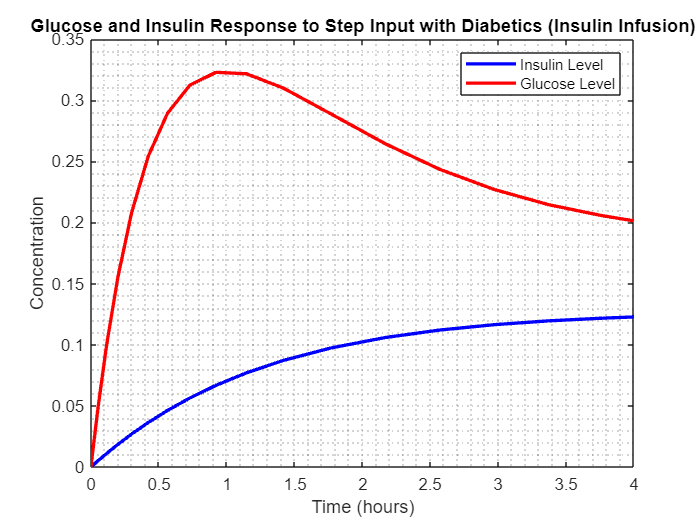

% Solve and plot glucose-insulin step input response for a subject with diabetics with insulin infusion
[time, state] = ode23(@glucose_infusion_model, [0 4], [0 0]);
figure;
plot(time, state(:,1), 'b-', 'LineWidth', 2, 'DisplayName', 'Insulin Level');
hold on;
plot(time, state(:,2), 'r-', 'LineWidth', 2, 'DisplayName', 'Glucose Level');
xlabel('Time (hours)');
ylabel('Concentration');
title('Glucose and Insulin Response to Step Input with Diabetics (Insulin Infusion)');
legend('Location', 'northeast');
grid minor;

### Question 02

Following is the simulation for Rigg's Iodine model with 150 ug intake for 10 days.

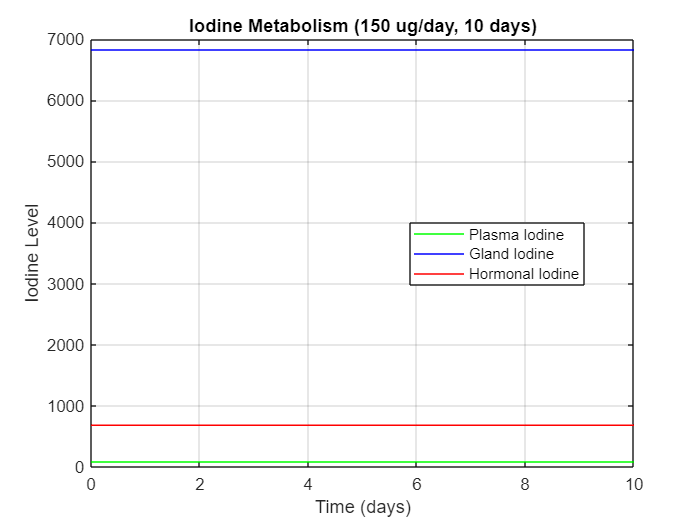

% Simulate iodine model for 150 ug/day 
%for 10 days
[time, state] = ode23(@iodine_high_intake, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Iodine Metabolism (150 ug/day, 10 days)');
legend('Location', 'best');
grid on;

Following is the simulation for Rigg's Iodine model with 150 ug intake for 300 days.

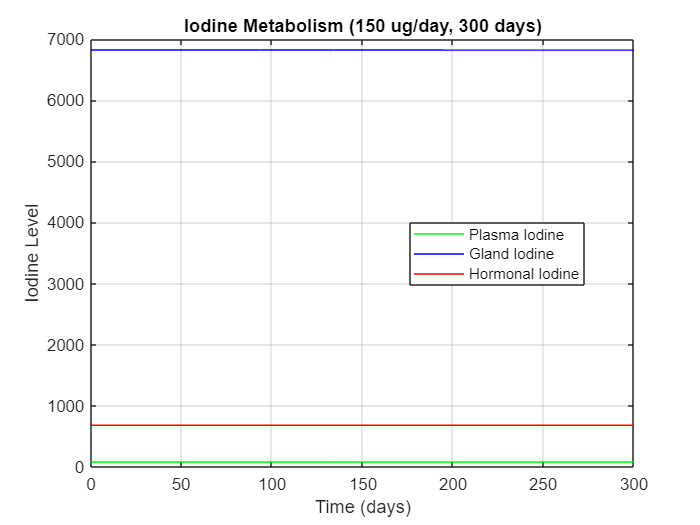

% Simulate iodine model for 150 ug/day 
%for 300 days
clc;
clear;
close all;

[time, state] = ode23(@iodine_high_intake, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Iodine Metabolism (150 ug/day, 300 days)');
legend('Location', 'best');
grid on;

Following is the simulation for Rigg's Iodine model with 15 ug intake for 10 days.

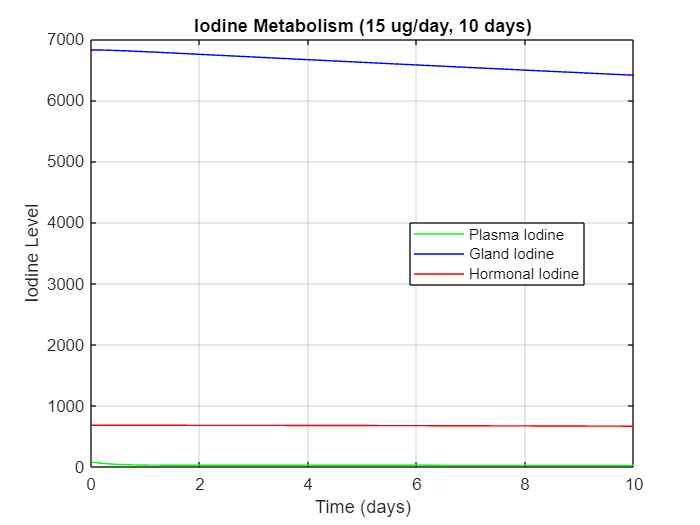

% Simulate iodine model for 15 ug/day
%for 10 days
clc;
clear;
close all;

[time, state] = ode23(@iodine_low_intake, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Iodine Metabolism (15 ug/day, 10 days)');
legend('Location', 'best');
grid on;

Following is the simulation for Rigg's Iodine model with 15 ug intake for 300 days.

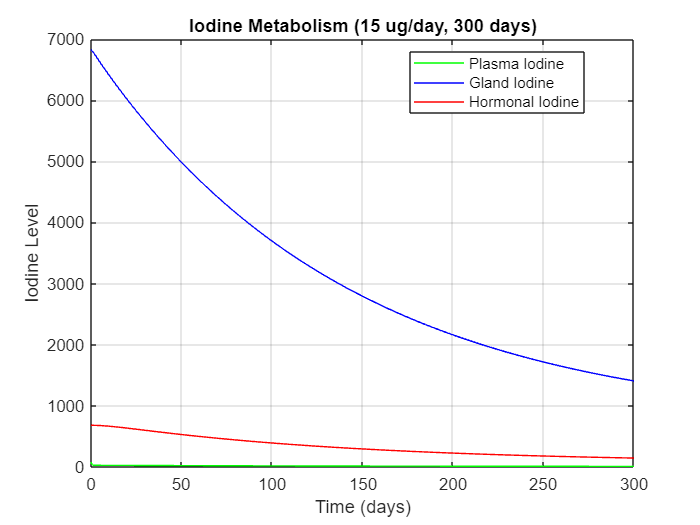

% Simulate iodine model for 15 ug/day
%for 300 days
[time, state] = ode23(@iodine_low_intake, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Iodine Metabolism (15 ug/day, 300 days)');
legend('Location', 'best');
grid on;

#### Part (a)

Hypothyroidism is a condition characterized by insufficient levels of thyroid hormones compared to normal, healthy levels. One common cause is autoimmune disease, where the immune system attacks and destroys the cells responsible for producing these hormones. As a result, thyroid hormone production decreases. In the Riggs model, this condition can be simulated by reducing the parameter k_2� to 0.005 representing a slower conversion of glandular iodine into hormonal iodine.

Following is the simulation for 10 days with intake of 150 ug per day.

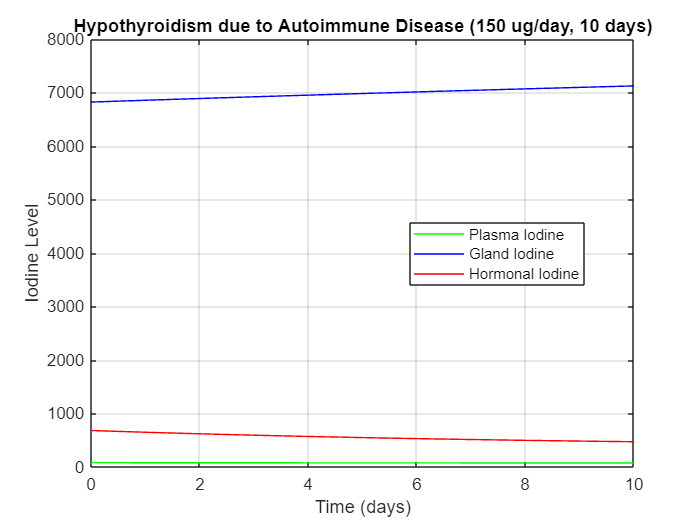

% Simulate Hypothyroidism due to autoimmune disease for 150 ug/day
%for 10 days
clc;
clear;
close all;

[time, state] = ode23(@iodine_hypo_autoimmune, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Hypothyroidism due to Autoimmune Disease (150 ug/day, 10 days)');
legend('Location', 'best');
ylim([0 8000]); 
grid on;

Following is the simulation for 300 days with intake of 150 ug per day.

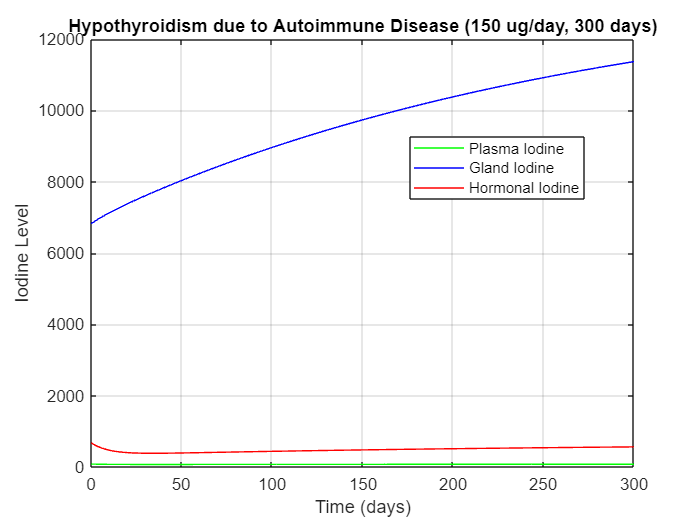

% Simulate Hypothyroidism due to autoimmune disease for 150 ug/day
%for 300 days

clc;
clear;
close all;

[time, state] = ode23(@iodine_hypo_autoimmune, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Hypothyroidism due to Autoimmune Disease (150 ug/day, 300 days)');
legend('Location', 'best');
grid on;

#### Part (b)

Hypothyroidism can also arise from inadequate iodine intake which is essential for the synthesis of thyroid hormones. In the context of the Riggs model, this scenario can be simulated by reducing the input function B_1(t) to 50. This adjustment reflects the diminished availability of iodine, leading to decreased thyroid hormone production and thereby mimicking the physiological effects of iodine deficiency-induced hypothyroidism.

Following is the simulation for 10 days.

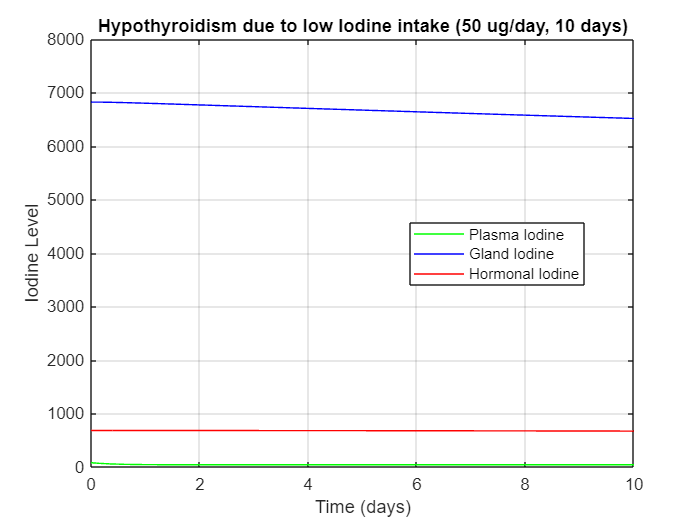

% Simulate Hypothyroidism due to low Iodine intake for 50 ug/day
%for 10 days

clc;
clear;
close all;

[time, state] = ode23(@riggs_low_iodine_intake, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Hypothyroidism due to low Iodine intake (50 ug/day, 10 days)');
legend('Location', 'best');
ylim([0 8000]); 
grid on;

Following is the simulation for 300 days.

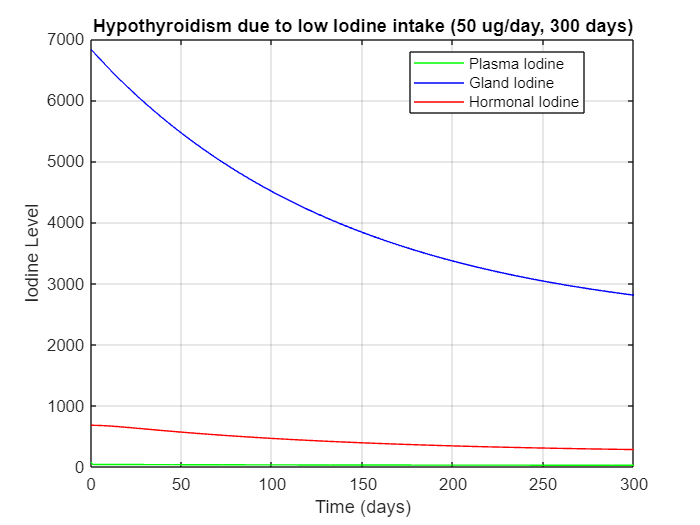

% Simulate Hypothyroidism due to low Iodine intake for 50 ug/day
%for 300 days
[time, state] = ode23(@riggs_low_iodine_intake, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Hypothyroidism due to low Iodine intake (50 ug/day, 300 days)');
legend('Location', 'best');
grid on;

#### Part (c)

Grave's disease is a condition characterized by the overproduction of thyroid hormones, often due to an overactive thyroid gland producing excessive iodine. This behavior can be modeled using the Riggs model by increasing the k_2� parameter to 0.08. This adjustment represents an accelerated conversion of glandular iodine into hormonal iodine, effectively simulating the heightened thyroid activity observed in Grave's disease.

Following is the simulation for 10 days with intake of 150 ug per day.

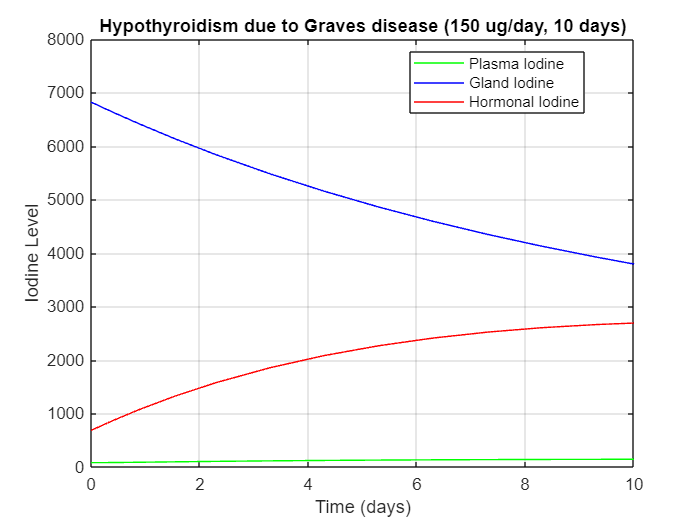

% Simulate Hypothyroidism due to Grave's disease intake for 150 ug/day
%for 10 days
clc;
clear;
close all;

[time, state] = ode23(@iodine_hyper_graves, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Hypothyroidism due to Graves disease (150 ug/day, 10 days)');
legend('Location', 'best');
ylim([0 8000]); 
grid on;

Following is the simulation for 300 days with intake of 150 ug per day.

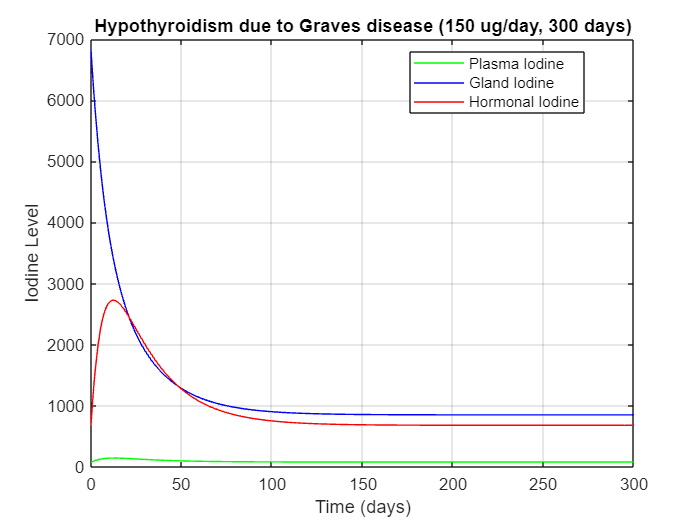

% Simulate Hypothyroidism due to Grave's disease intake for 150 ug/day
%for 300 days

[time, state] = ode23(@iodine_hyper_graves, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Hypothyroidism due to Graves disease (150 ug/day, 300 days)');
legend('Location', 'best');
grid on;

#### Part (d)-Goitre

Goiter is a condition characterized by the abnormal enlargement of the thyroid gland, most commonly caused by insufficient iodine in the diet. Iodine is an essential element required for the synthesis of thyroid hormones. When iodine intake is too low, the thyroid gland cannot produce adequate hormones triggering the pituitary gland to release more thyroid-stimulating hormone (TSH). In response, the thyroid gland enlarges in an attempt to absorb more iodine and compensate for the hormone deficiency. In the Riggs model, dietary iodine intake is represented by the input B_1(t). By reducing the value of B_1(t) from 150 to 25, we can simulate the iodine-deficient conditions that lead to goiter development.

Following is the simulation for 10 days.

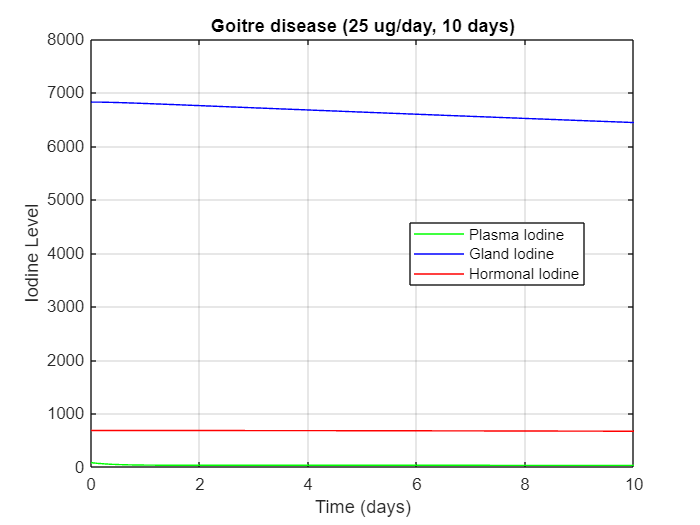

% Simulate Goitre disease intake for 25 ug/day
%for 10 days
clc;
clear;
close all;

[time, state] = ode23(@iodine_goitre, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Goitre disease (25 ug/day, 10 days)');
legend('Location', 'best');
ylim([0 8000]); 
grid on;

Following is the simulation for 300 days.

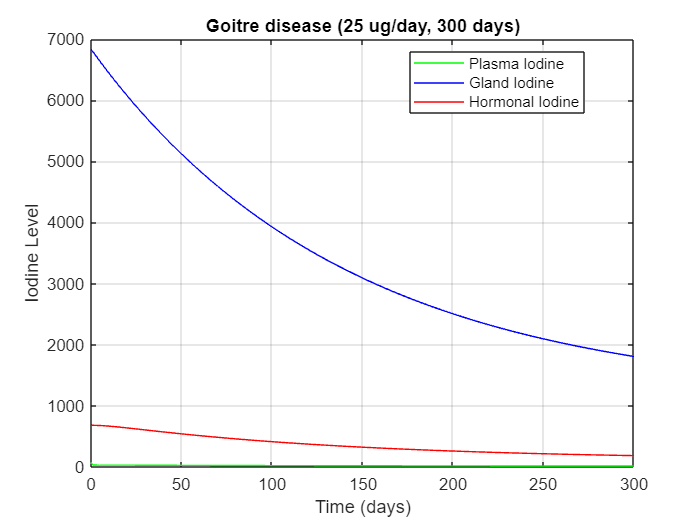

% Simulate Goitre disease intake for 25 ug/day
%for 300 days
[time, state] = ode23(@iodine_goitre, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Goitre disease (25 ug/day, 300 days)');
legend('Location', 'best');
grid on;

#### Part (d)-Tumor

Thyroid nodules, which are abnormal growths or tumors within the thyroid gland can sometimes lead to excessive production of thyroid hormones. These nodules may become overactive, functioning independently of normal regulatory mechanisms and continuously releasing hormones, a condition known as toxic nodular goiter. This uncontrolled hormone production results in hyperthyroidism and is typically associated with an increased conversion rate of glandular iodine to hormonal iodine. In the Riggs model, this behavior can be mimicked by increasing the k_2 parameter. Raising the k_2� value from 0.01 to 0.1 represents this heightened conversion process, effectively modeling the physiological impact of thyroid nodules on hormone levels.

Following is the simulation for 10 days with intake of 150 ug per day.

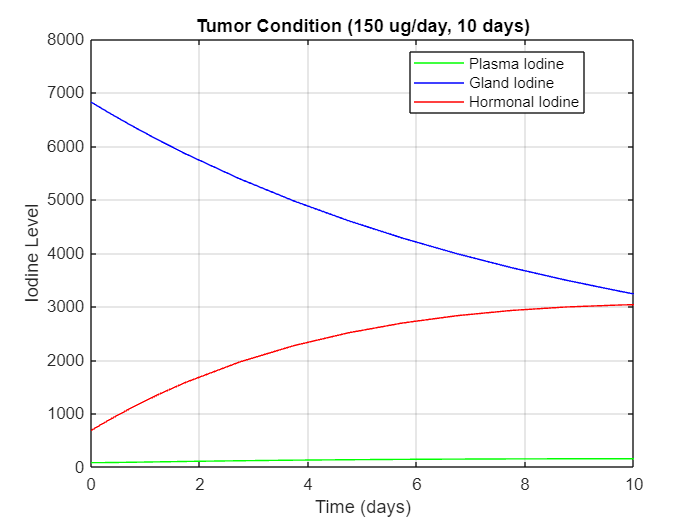

% Simulate Tumor Condition intake for 150 ug/day
%for 10 days
clc;
clear;
close all;

[time, state] = ode23(@iodine_tumor, [0 10], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Tumor Condition (150 ug/day, 10 days)');
legend('Location', 'best');
ylim([0 8000]);
grid on;

Following is the simulation for 10 days with intake of 150 ug per day.

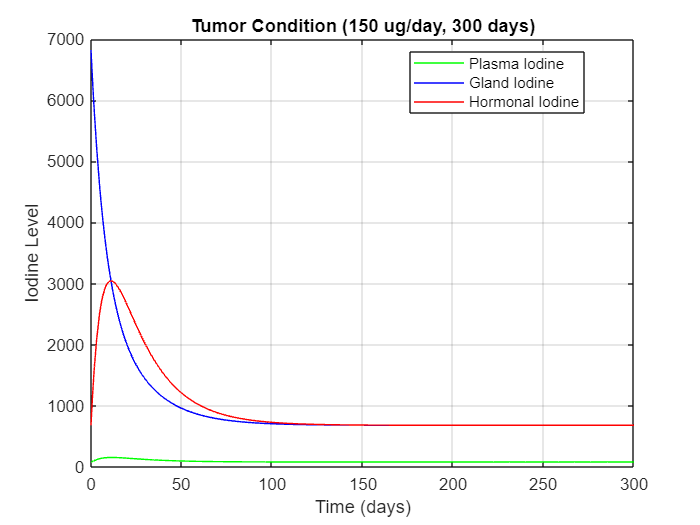

% Simulate Tumor Condition intake for 150 ug/day
%for 300 days

[time, state] = ode23(@iodine_tumor, [0 300], [81.2 6821 682]);
figure;
plot(time, state(:,1), 'g-', 'DisplayName', 'Plasma Iodine');
hold on;
plot(time, state(:,2), 'b-', 'DisplayName', 'Gland Iodine');
plot(time, state(:,3), 'r-', 'DisplayName', 'Hormonal Iodine');
xlabel('Time (days)');
ylabel('Iodine Level');
title('Tumor Condition (150 ug/day, 300 days)');
legend('Location', 'best');
grid on;

## Part 3

### Question 01

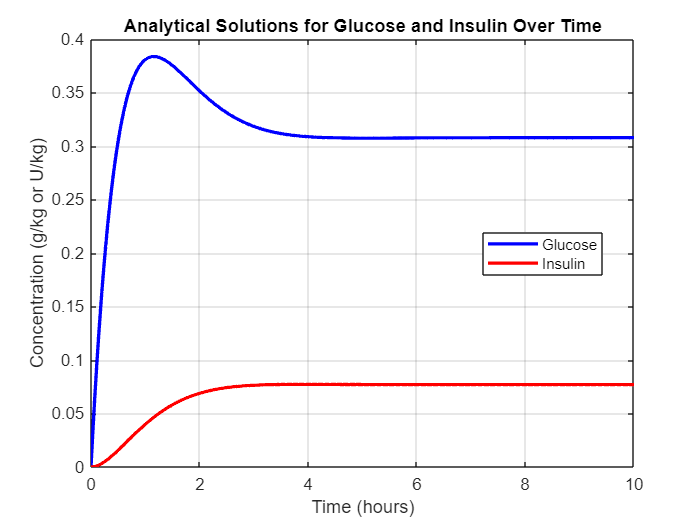

% Analytical solutions for glucose-insulin model
clear all; close all;

% Define time range from 0 to 10 hours with 0.01 step
time_values = 0:0.01:10;

% Analytical solutions
glucose_level = (4/13) + exp(-1.4 * time_values) .* ((-4/13) * cos(0.8 * time_values) + (37/52) * sin(0.8 * time_values));
insulin_level = (1/13) + exp(-1.4 * time_values) .* ((-1/13) * cos(0.8 * time_values) + (-7/52) * sin(0.8 * time_values));

% Generate plot
figure;
plot(time_values, glucose_level, 'b-', 'LineWidth', 2, 'DisplayName', 'Glucose');
hold on;
plot(time_values, insulin_level, 'r-', 'LineWidth', 2, 'DisplayName', 'Insulin');
grid on;
legend('Location', 'best');
xlabel('Time (hours)');
ylabel('Concentration (g/kg or U/kg)');
title('Analytical Solutions for Glucose and Insulin Over Time');

Insulin, a hormone secreted by the beta cells of the pancreas plays a key role in regulating blood glucose levels by promoting the conversion of excess glucose into glycogen for storage in the liver and muscles. According to the graph, insulin levels begin to rise shortly after glucose levels peak. This slight delay is due to the time required for pancreatic cells to detect increased glucose and initiate insulin secretion. Eventually, both glucose and insulin levels stabilize, reaching a steady state where they remain relatively constant reflecting a balanced physiological response.

### Question 02

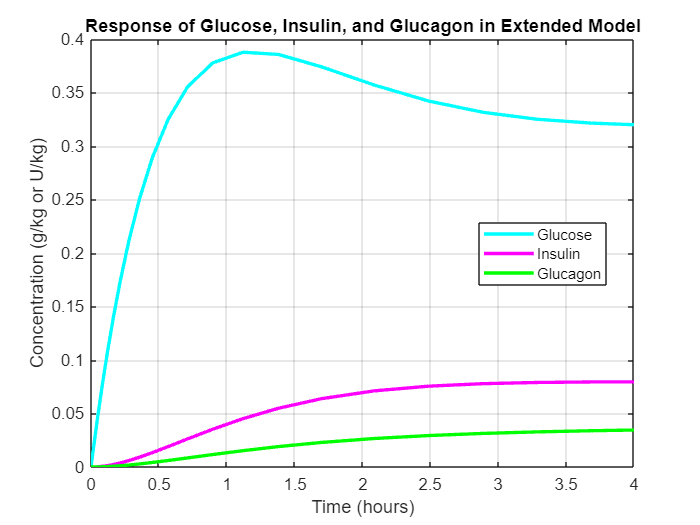

% Define simulation parameters
time_interval = [0 4]; % Simulate for 4 hours
start_conditions = [0 0 0]; % Initial conditions: [glucose, insulin, glucagon]

% Solve the system using ode23 with the external function
[time_data, state_concentrations] = ode23(@bolie_extended_model, time_interval, start_conditions);

%% Plotting Results

% Create a figure to visualize the dynamics
figure;
plot(time_data, state_concentrations(:,1), 'c-', 'LineWidth', 2, 'DisplayName', 'Glucose');
hold on;
plot(time_data, state_concentrations(:,2), 'm-', 'LineWidth', 2, 'DisplayName', 'Insulin');
plot(time_data, state_concentrations(:,3), 'g-', 'LineWidth', 2, 'DisplayName', 'Glucagon');
grid on;
legend('Location', 'best');
xlabel('Time (hours)');
ylabel('Concentration (g/kg or U/kg)');
title('Response of Glucose, Insulin, and Glucagon in Extended Model');

The graph shows how insulin and glucagon work together to keep our blood sugar levels in balance. After a big dose of glucose, insulin levels start to rise quickly just after the glucose levels go up. This small delay happens because the pancreas needs a moment to sense the spike in blood sugar before it can release insulin.

When glucagon is present, blood sugar levels stay higher at the end of the simulation compared to when it's not. That’s because glucagon has the opposite effect of insulin. It tells the liver to release stored glucose, which helps keep blood sugar levels from dropping too much.

Even though the body produces more insulin in response to glucagon, the interaction between the two hormones results in a higher final glucose level when glucagon is involved. This pattern aligns well with what Bolie’s model predicts, showing that it accurately reflects how our bodies manage blood sugar.